# Lab 5 – Convolution 

# EE252L/CE251L: Signalsand Systems Lab

### Dr. Basit Memon and Ms. Hira Mustafa

Name: M Shees Abbas

id: ma11212

## Task 1

1) Does the order of inputs matter? Is convolution always commutative, i.e. is  *u*(*t*) ∗ *v* (*t*) = *v* (*t*) ∗ *u*(*t*)?

A) yes the convolution is commutative because if even we interchange the both funtions u(t) and             v(t) the convolution output stays the same

2) Describe your general observations about the convolution output w compared to the inputs u and v?

A) I observed by looking at the output of both functions u(t) and v(t) that the output that come was the magnitude of area under both u(t) and v(t) curves at that point in time when one of the function is fixed in time and the other function is at t and the convolution was maximum when t becomes equal to  (the coordinates of fixed function in time axis)

## Task 2

1) How is the length of convolution output related to the length *L* of the two input signals?

A)the length of convolution is equal to (2L)-1 where L is the length of both funtions

2) What do you think will happen if the input sequences had different lengths? say,*M* and *N*, instead of *L*.

A) If we take the length of each function as M and N the length of the convolutions becomes (M+N) -1 

## Task 3

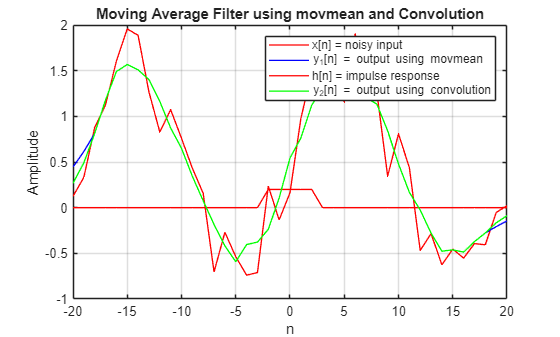

clc;
clear close all;
n = -20:20;
z = sin(0.3142*n);
noise = rand(size(n));
x= z + noise;
y1 = movmean(x,5);
delta = (n==0);
h = movmean(delta, 5);
y2 = conv(x,h, "same");
figure;
plot(n, x,'r-', 'LineWidth', 1);
hold on;
plot(n, y1,'b-','LineWidth', 1);
plot(n, h, 'r-','LineWidth', 1);
plot(n, y2,'g-','LineWidth', 1);
grid on;
xlabel('n');
ylabel('Amplitude');
title('Moving Average Filter using movmean and Convolution');
legend('x[n] = noisy input', 'y_1[n] = output using movmean','h[n] = impulse response', 'y_2[n] = output using convolution');

## Task 5

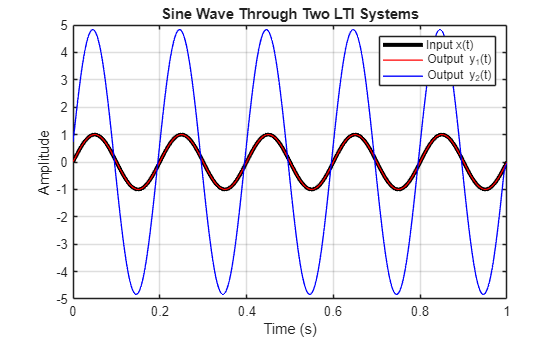

clc;
clear close all;

Fs = 1000;
t = 0: 1/Fs : 1;
f0 = 5;
x = sin(2*pi*f0*t);

h1 = ones(1,5)/5;

n  = 0:15;
h2 = (0.8).^n;

y1 = conv(x, h1, 'same');
y2 = conv(x, h2, 'same');

figure;              
plot(t, x, 'k',LineWidth=3);      
hold on;             
plot(t, y1, 'r',LineWidth=1);      
plot(t, y2, 'b', LineWidth=1);    
hold off;            

grid on;              
xlabel('Time (s)');   
ylabel('Amplitude');  
title('Sine Wave Through Two LTI Systems');  
legend('Input x(t)', 'Output y_1(t)', 'Output y_2(t)');

[pks1, locs1] = findpeaks(y1, t);
T1 = locs1(2) - locs1(1);
f1 = 1/T1;

[pks2, locs2] = findpeaks(y2, t);
T2 = locs2(2) - locs2(1);
f2 = 1/T2;

disp("Input Frequency: " + f0)

Input Frequency: 5


disp("System 1:");

System 1:


disp("Time Period T1: " + T1)

Time Period T1: 0.2


disp("Frequency f1: " + f1)

Frequency f1: 5


disp("System 2:");

System 2:


disp("Time Period T2: " + T2)

Time Period T2: 0.2


disp("Frequency f2: " + f2)

Frequency f2: 5


## Task 6

[h, Fh] = audioread("C:\Users\ma11212\University-work\SNS\lab 5\1st_baptist_nashville_balcony.wav"); 
disp(size(h))

      288000           2



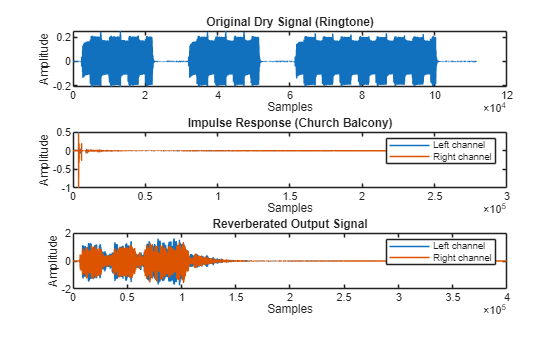


soundsc(h,Fh) % Play the sound
pause(length(h)/Fh) % Wait for audio to finish playing

[x, Fx] = audioread("C:\Users\ma11212\University-work\SNS\lab 5\ringtone.wav"); % Read input disp(size(x))
soundsc(x,Fx) % Play the sound
pause(length(x)/Fx) % Wait for audio to finish playing

h1 = h(:,1); % Extract the first channel from the impulse response
%In simple words extracting all the rows of first column
h2 = h(:,2); % Extract the second channel from the impulse respose
%ISimilarly extracting all the rows of second column of h

y1 = conv(h1, x);
y2 = conv(h2, x);

% Concatenate into stereo output
y = [y1, y2];

% Play the reverberated sound
soundsc(y, Fx)
pause(length(y)/Fx)

%% Plot the signals
figure;

subplot(3,1,1);
plot(x);
title('Original Dry Signal (Ringtone)');
xlabel('Samples'); ylabel('Amplitude');

subplot(3,1,2);
plot(h); 
title('Impulse Response (Church Balcony)');
xlabel('Samples'); ylabel('Amplitude');
legend('Left channel','Right channel');

subplot(3,1,3);
plot(y);
title('Reverberated Output Signal');
xlabel('Samples'); ylabel('Amplitude');
legend('Left channel','Right channel');